# Rahmen

clear
addpath('../../../../../04-software/bofem/src')
addpath('lib')
import bofem.*;

## System

m = Model();
m.addMaterial(Material.STEEL_S235);
m.addSection('I', 'IPE600', 0.22, 0.6, 0.012, 0.019, 0.024);
m.addSection('I', 'HEA300', 0.30, 0.29, 0.0085, 0.014, 0.027);
m.addNodes([0, 6, 22, 27], zeros(1, 4));
m.addNodes([6, 27], [5, 5]);
m.useElementType = 'Beam2D';
m.useSection = 1;
m.addElements(1:3, 2:4);
m.useSection = 2;
m.addElements([5, 6], [2, 4]);
m.setLoad(1:3, 7.5);
m.setForce(3, [0, 35]);
m.setConstraint(5, [true, true, true]);
m.setConstraint(6, [true, true, false]);

## Ergebnisse

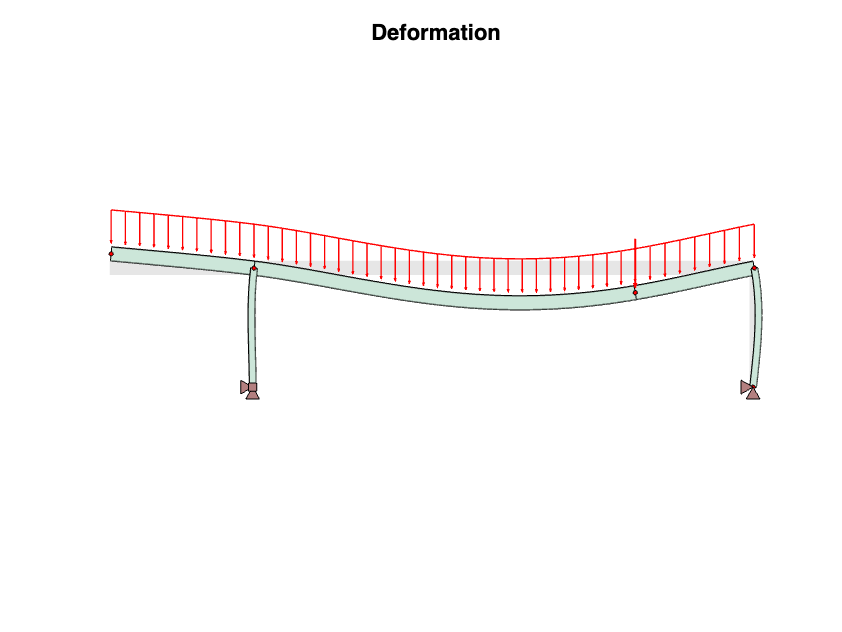

m.solve();
v = Visualizer(m);
v.update()
v.drawElementsDeformed = true;
v.update()

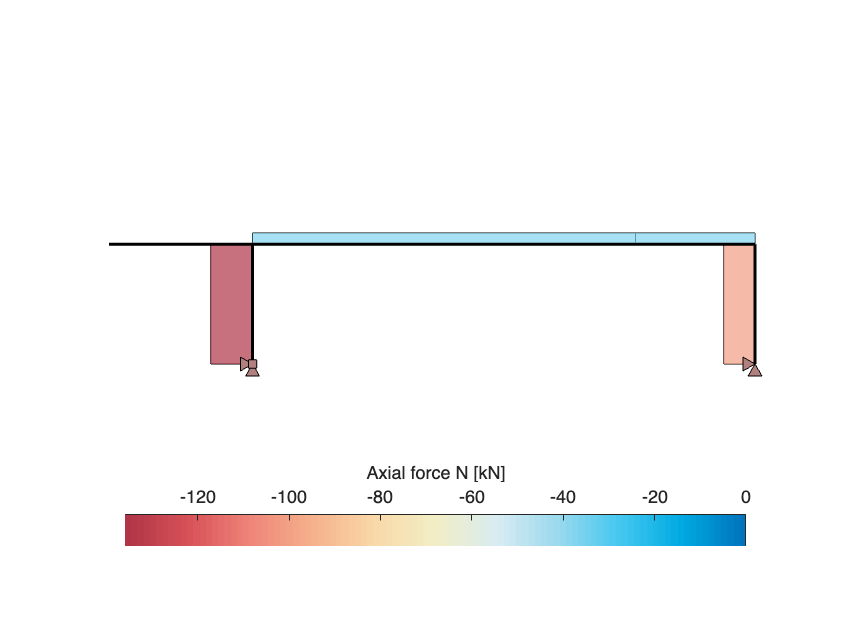

v.drawElementsDeformed = false;
v.drawElementResult = 'N';
v.update()

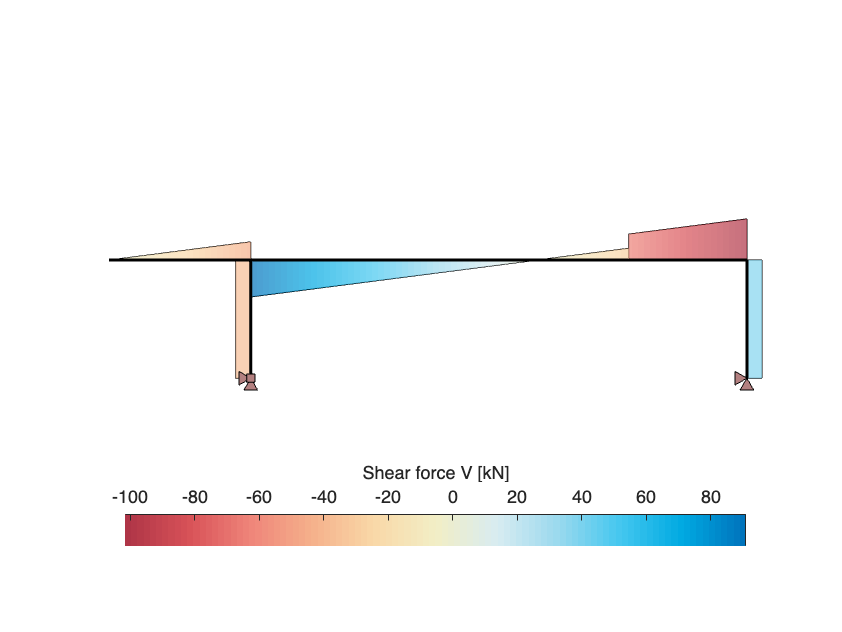

v.drawElementResult = 'V';
v.update()

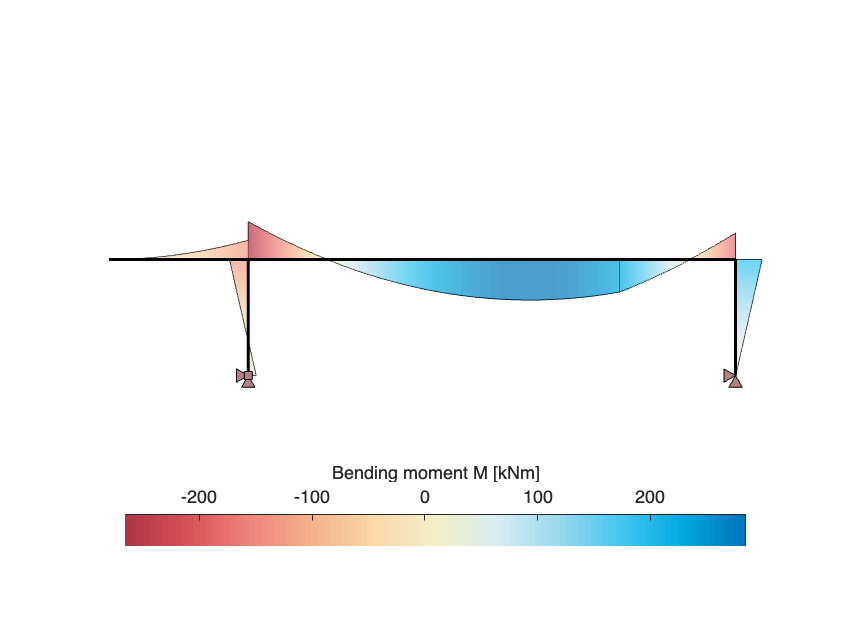

v.drawElementResult = 'M';
v.update()

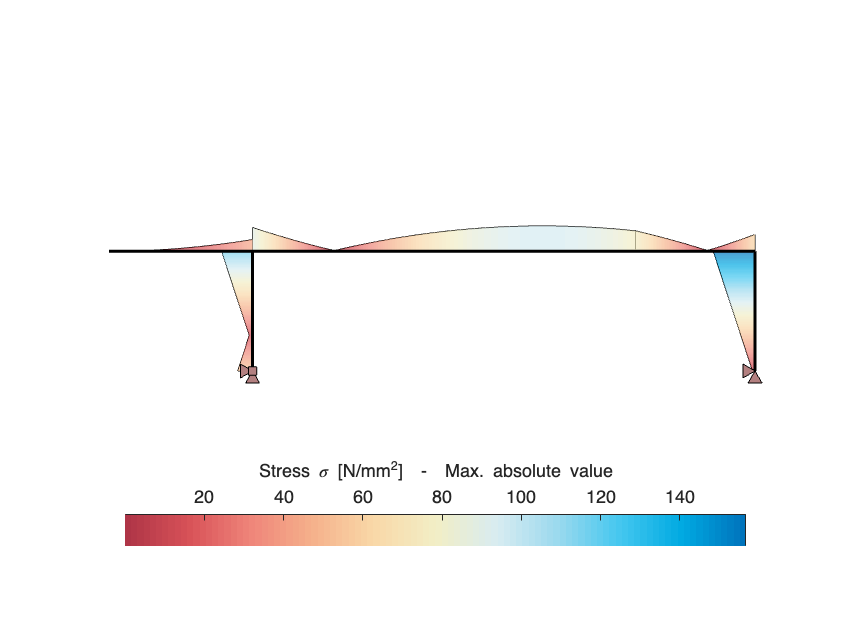

v.scaleElementResult = -1;
v.drawElementResult = 'sigma';
v.update()

Zahlenwerte

mmMax = round(1e-3 * mMax(m), 3)

mmMax = 284.7640

wwMax = round(1e3 * wMax(m), 3)

wwMax = 57.4260

smax = round(1e-6 * sigmaMax(m), 3)

smax = 156.7020